## SAD

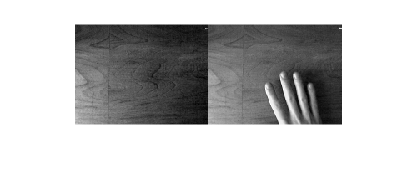

vidObj = VideoReader('motion1.avi');
im0 = read(vidObj, 1);
im1 = read(vidObj, 55);
im0gray = rgb2gray(im0);
im1gray = rgb2gray(im1);
imshowpair(im0gray, im1gray, 'montage')

%normalne odjemowanie obrazów (słabe bo przepełnienia się zmienna)
d1 = im0gray - im1gray;

Unrecognized function or variable 'im0gray'.

[im0gray(70,90) im1gray(70,90) d1(70,90)]
imtool(d1, [])
[double(min(d1(:))) double(max(d1(:)))]

% wybieramy pixele o współrzędnych wiersz=70, kolumna=90
[im0gray(70,90) im1gray(70,90) d1(70,90)]

ans = 1×3 uint8 row vector
   109   208     0


class(im0gray)

ans = 'uint8'

% w narzędziu pixel region wartość pixela 70x90 to 0

%odejmowanie obrazów z konwersją na double (większy range)
d2 = double(im0gray) - double(im1gray);
[double(im0gray(70,90)) double(im1gray(70,90)) d2(70,90)]

ans =    109   208   -99


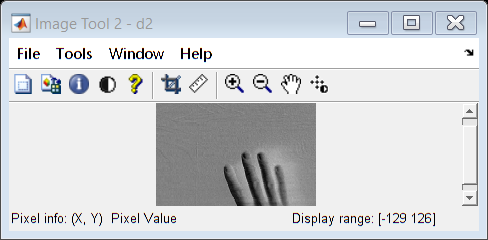

imtool(d2, [])

[double(min(d2(:))) double(max(d2(:)))]

ans =   -129   126


%odejmowanie z im2double(najlepsza opcja)
d3 = im2double(im0gray) - im2double(im1gray);
[im2double(im0gray(70,90)) im2double(im1gray(70,90)) d3(70,90)]

ans =     0.4275    0.8157   -0.3882


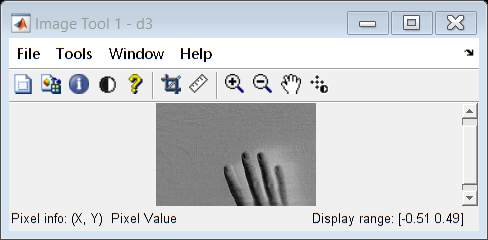

imtool(d3,[])

[double(min(d3(:))) double(max(d3(:)))]

ans =    -0.5059    0.4941


%imabsdiff
d4 = imabsdiff(im0gray, im1gray);
d4(70,90)

ans = uint8
99

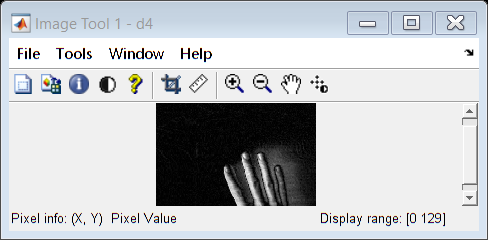

imtool(d4, [])

[double(min(d4(:))) double(max(d4(:)))]

ans =      0   129


%obraz jest inny niż przy poprzednich, ale to pewnie winna braku ujemnych
%wartości dla pikseli
%nie zapomnij porównać tych wartości d1,d2,d3,d4

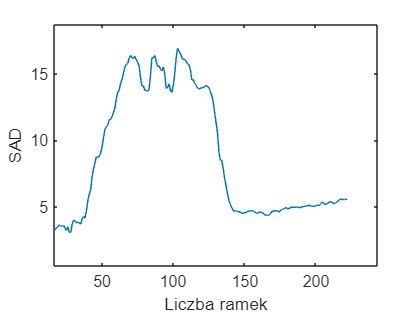

%SAD -dla obrazu tłą im0
T = readtable('movout.txt'); % wczytanie danych z pliku txt jako typ danych Table
figure;plot(T.sad);ylabel("SAD");xlabel("Liczba ramek")


%ustawiony próg detekcji na początku - 12
%ten próg 12 jest dosyć optymalny, na tym wykresie widac kiedy ręka rusza
%się najbardziej

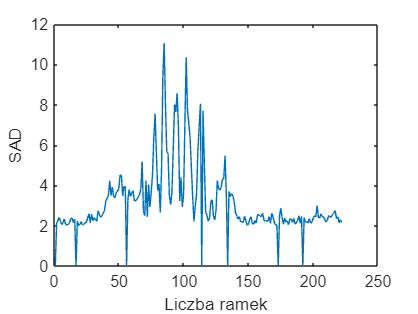

%SAD - dla różnicy między poszczególnymi ramkami
T = readtable('movout.txt'); % wczytanie danych z pliku txt jako typ danych Table
figure;plot(T.sad);ylabel("SAD");xlabel("Liczba ramek")

%są takie wahania SAD, że nie da się wyznaczyć dobrego progu, bo ma
%straszne spiki

## MHI

exportObj =   myExportData with no properties.
